InitBreach;
clc;
clear S;
close all;

Specify Video File

% videoFileName = '05_highway_lanechange_25s.mp4';

x0_host = 0;
v0_host = 20;
vref_host = 20;
Ts = 0.05;
endTime = 498; % Ignore the first 2 values as they are not sensed
dSafe = 2;

% The file TrackLeadVehicle modifies the code taken from Matlab reference
% example to calculate the all lead car positions and saves that in a
% matlab file. This script loads from the saved file and calculates the
% lead car position at each time step (i.e., in each frame of video).

% Setup Video Reader and Player
% videoReader = VideoReader(videoFileName);
% videoPlayer = vision.DeployableVideoPlayer();

%%%%% MODIFY THIS %%%%%%%
lead_car_pos = 20*ones(endTime, 1); 
a = load('AllLeadVehicles_Part2.mat', 'leadVehicles');
for i = 1:numel(lead_car_pos) 
    c_lead_pos = 20;
    currentLeadVehicles = a.leadVehicles{i+2}; % Ignore the first 2 values as they are not sensed
    minY = 100.0;
    for j = 1:numel(currentLeadVehicles)
        lv = currentLeadVehicles{j};
        if (lv(2) < minY)
            c_lead_pos = lv(1);
            minY = lv(2);
        end
    end
    lead_car_pos(i) = c_lead_pos;
end

S = BreachSimulinkSystem('ACC_HW3');

Found var Ts in base workspace used by ACC_HW3_breach.
Found var dSafe in base workspace used by ACC_HW3_breach/Adaptive Cruise Control System/Constant.
Found var v0_host in base workspace used by ACC_HW3_breach/Constant.
Found var vref_host in base workspace used by ACC_HW3_breach/Host Car/Saturation.
Found var x0_host in base workspace used by ACC_HW3_breach/Constant1.


tspan = 0:Ts:endTime;
S.SetTime(tspan);
inputGen.type = 'UniStep';
inputGen.cp = endTime;
S.SetInputGen(inputGen);
params = cell(1,endTime);
for jj=1:endTime
    params{1,jj} = sprintf('dist_u%d',jj-1);
end

S.PrintParams;

-- PARAMETERS --
Ts=0.05       
dSafe=2       
v0_host=20       
vref_host=20       
x0_host=0       
dist_u0=0       
dist_u1=0       
dist_u2=0       
dist_u3=0       
dist_u4=0       
dist_u5=0       
dist_u6=0       
dist_u7=0       
dist_u8=0       
dist_u9=0       
dist_u10=0       
dist_u11=0       
dist_u12=0       
dist_u13=0       
dist_u14=0       
dist_u15=0       
dist_u16=0       
dist_u17=0       
dist_u18=0       
dist_u19=0       
dist_u20=0       
dist_u21=0       
dist_u22=0       
dist_u23=0       
dist_u24=0       
dist_u25=0       
dist_u26=0       
dist_u27=0       
dist_u28=0       
dist_u29=0       
dist_u30=0       
dist_u31=0       
dist_u32=0       
dist_u33=0       
dist_u34=0       
dist_u35=0       
dist_u36=0       
dist_u37=0       
dist_u38=0       
dist_u39=0       
dist_u40=0       
dist_u41=0       
dist_u42=0       
dist_u43=0       
dist_u44=0       
dist_u45=0       
dist_u46=0       
dist_u47=0       
dist_u48=0       
dist_u49=0       
dist_u50

S.SetParam(params, lead_car_pos(1:endTime));
S.PrintParams;

-- PARAMETERS --
Ts=0.05       
dSafe=2       
v0_host=20       
vref_host=20       
x0_host=0       
dist_u0=10.6411       
dist_u1=12.4022       
dist_u2=13.1206       
dist_u3=13.187       
dist_u4=12.8838       
dist_u5=13.0275       
dist_u6=13.2896       
dist_u7=13.6107       
dist_u8=12.9073       
dist_u9=12.9869       
dist_u10=12.8273       
dist_u11=21.0079       
dist_u12=22.1104       
dist_u13=20.4017       
dist_u14=19.3245       
dist_u15=19.1763       
dist_u16=19.0298       
dist_u17=18.8856       
dist_u18=18.7435       
dist_u19=18.6035       
dist_u20=23.3281       
dist_u21=24.5705       
dist_u22=25.102       
dist_u23=25.6973       
dist_u24=25.982       
dist_u25=26.273       
dist_u26=17.5576       
dist_u27=17.227       
dist_u28=17.3981       
dist_u29=17.5726       
dist_u30=17.7507       
dist_u31=14.3217       
dist_u32=13.928       
dist_u33=13.2994       
dist_u34=12.8967       
dist_u35=12.5177       
dist_u36=12.1603       
dist_u37=11.8227       
di

numSimulations = 1;
S.QuasiRandomSample(numSimulations);
S.Sim;

clc;

STL_ReadFile('./ACC_Requirements.stl');
disp('Checking safe following ..');

Checking safe following ..


robs1 = S.CheckSpec(safeFollowing);
disp(robs1);

    7.7965



disp('Checking forward progress');

Checking forward progress


robs2 = S.CheckSpec(forwardProgress);
disp(robs2);

    0.0182



disp('Checking if cruising works');

Checking if cruising works


robs3 = S.CheckSpec(cruiseWhenNotImpeded);
disp(robs3);

     2



disp('Checking that the host stops only if required');

Checking that the host stops only if required


robs4 = S.CheckSpec(dontStopUnlessLeadStops);
disp(robs4);

   16.3745



## Pretty-printing plots by getting signal values and grouping them

together. DO NOT USE this if numSimulations is a large number, because Matlab will open 'numSimulations' figure windows, and it could slow down your Matlab or even cause it to crash!

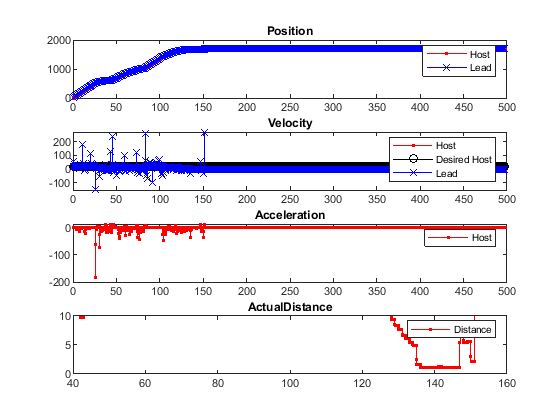

% signalValues = S.GetSignalValues({'HostPosition','LeadPosition'});
% close all;
% 
% % as a safeguard, you could use min(numSimulations,20) instead of
% % numSimulations as the loop termination condition below:
% figure;
% trace = signalValues;
% subplot(5,1,1);
% plot(tspan,trace(1,:),'-r.', tspan, trace(2,:), '-bx');
% title('Position');

signalValues = S.GetSignalValues({'HostPosition','LeadPosition',...
                               'HostVelocity',...
                               'HostAcceleration','LeadVelocity',...
                               'ActualDistance'});
close all;

% as a safeguard, you could use min(numSimulations,20) instead of
% numSimulations as the loop termination condition below:
figure;
trace = signalValues;
subplot(4,1,1);
plot(tspan,trace(1,:),'-r.', tspan, trace(2,:), '-bx');
% title, legend code courtesy Ryan Blackwell
title('Position');
legend('Host','Lead');

subplot(4,1,2);    
plot(tspan,trace(3,:),'-r.', ...
     tspan, vref_host*ones(1,length(tspan)),'-ko', ... 
     tspan,trace(5,:),'-bx');   
title('Velocity');
legend('Host','Desired Host','Lead');

subplot(4,1,3);
plot(tspan,trace(4,:),'-r.');
title('Acceleration');
legend('Host');

subplot(4,1,4);
plot(tspan,trace(6,:),'-r.');
title('ActualDistance');
legend('Distance');
ylim([0, 10])